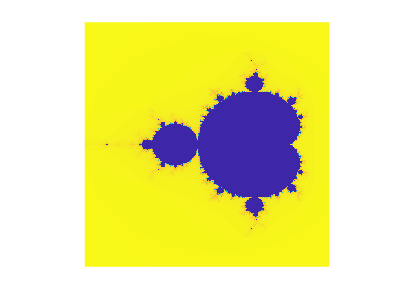

function main
    pixelPerUnit = 300;
    width = pixelPerUnit;
    height = pixelPerUnit;
    leftUp = -2 + 1.5i; rightButtom = 0.7 - 1.5i;
    deltaReel = real(rightButtom - leftUp)/width;
    deltaImag = 1i*imag(leftUp - rightButtom)/height;
    z0 = leftUp + deltaReel/2-deltaImag/2;
    IM = uint8(zeros(height,width));
    for k1 = 1:height
        for k2 = 1:width
           IM(k1,k2)=Mandelbrot(z0);
        z0 = z0+deltaReel;
        end
        fprintf('\n');
        z0 = real(leftUp)+deltaReel/2+1i*imag(z0)-deltaImag;
    end

    f = figure(1);
    cla;
    f.NumberTitle = 'off';
    f.Name = 'Mandelbrot-Set';
    f.MenuBar = 'none';
    image(IM);
    colormap default; axis off; axis equal;
end

function b = Mandelbrot(c)
d=0;
b= 0;
for j=1:256
    d=d^2+c;
    if abs(d)>2
        b=255-uint8(j);
        break;
    end
end
end
main()